# Zadanie 7 - sprawność fotoogniwa w modelu dwudiodowym

Symuluje się model dwudiodowy fotoogniwa, gdzie dane to powierzchnia A=100${\mathrm{cm}}^2$ ,$I_L =3\ldotp 5A,\;I_{01} ={10}^{-10} A,\;I_{02} ={10}^{-5} A$. Ogniwo badane w warunkach AM1.5.

clc; close all;
A=100; %[cm^2]
I_L=3.5; %[A]
I_01=1e-10;% [A]
I_02=1e-5;%[A]
PI_in=1000;%[W/m^2]
k=1.381e-23;%[J/K]
T=273.15+25;%[K]
q=1.602e-19;%[C]

Prosze wybrać wartość oporu szeregowego w miliohmach.

Rs=5.41202;%[mOhm]
Rs=Rs*1e-3;%[Ohm]

Prosze wybrać wartość oporu upływu w kilohmach.

Rsh =71.4466;%[kOhm]
Rsh=Rsh*1e3;%[Ohm]

U=linspace(-0.4,0.8,2000); %[V]
I_conv=zeros(1,2000); %[A]
I=zeros(1,100);
I(1,1)=0;
for j=1:size(U,2)
    for i=2:size(I,2)
        I(1,i)=I_L-I_01*exp(q*(U(1,j)+I(1,i-1)*Rs)/k/T)-I_02*exp(q*(U(1,j)+I(1,i-1)*Rs)/k/T/2)-(U(1,j)+I(1,i-1)*Rs)/Rsh;
    end
    I_conv(1,j)=I(end);
end

Wyniki dla symulacji w zadanych parametrach:

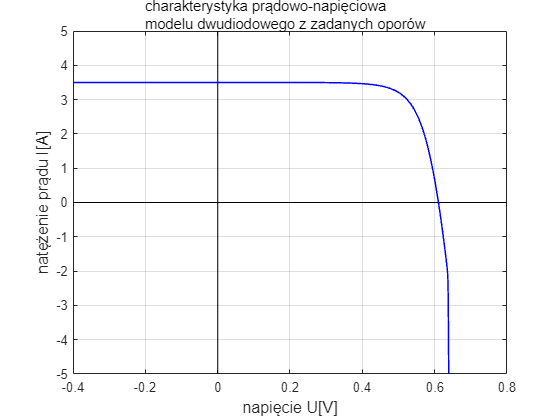

plot([min(U) max(U)], [0 0], 'Color', 'k');
hold on
xlim([min(U),max(U)]);
ylim([-5,5]);
plot([0 0], [-5,5], 'Color', 'k');
xlabel("napięcie U[V]","FontSize",12);
ylabel("natężenie prądu I[A]","FontSize",12);
plot(U,I_conv,'color','blue','LineWidth',1.1)
text(-0.2, 5.5,{'charakterystyka prądowo-napięciowa', 'modelu dwudiodowego z zadanych oporów'},'FontSize', 11);
grid on
hold off

P=U.*I_conv;%[U*I=W]
Pmax=max(P);
Pmax_in=Pmax/A*1e4; %[W/cm^2=W/m^2*10000]

eta=Pmax_in/PI_in;
fprintf("sprawność tego fotoogniwa to: η = " + num2str(eta) + "[1].");

sprawność tego fotoogniwa to: η = 0.16049[1].

etas=zeros(1,1e3);
Rsh_study=logspace(-5,2,1e3);
Rsh_study=Rsh_study*1e3;
for k=1:size(Rsh_study,2)
    for j=1:size(U,2)
        I(1,1)=0;
        for i=2:size(I,2)
            I(1,i)=I_L-I_01*exp(q*(U(1,j)+I(1,i-1)*Rs)/k/T)-I_02*exp(q*(U(1,j)+I(1,i-1)*Rs)/k/T/2)-(U(1,j)+I(1,i-1)*Rs)/Rsh_study(1,k);
        end
        I_conv(1,j)=I(end);
    end
    P=U.*I_conv;%[U*I=W]
    Pmax=max(P);
    Pmax_in=Pmax/A*1e4; %[W/cm^2=W/m^2*10000]
    etas(1,k)=Pmax_in/PI_in;
end

Następnie przeprowadzono badanie sprawności dla różnych wartości oporu upływu w skali półlogarytmicznej, opór szeregowy jest taki jak wcześniej zadał użytkownik.

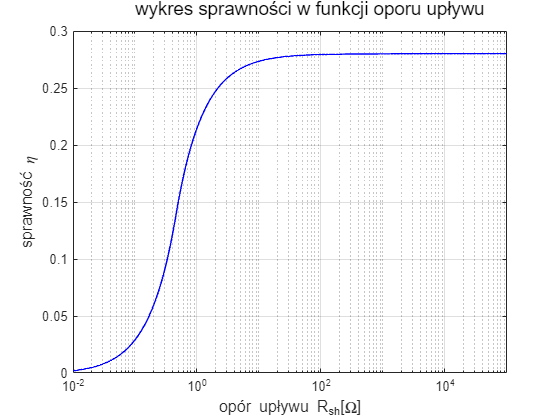

semilogx(Rsh_study,etas,'color','blue','LineWidth',1.1)
xlim([1e-2,1e5]);
xlabel("opór upływu R_{sh}[\Omega]","FontSize",12);
ylabel("sprawność \eta","FontSize",12);
text(1e-1, 0.32,'wykres sprawności w funkcji oporu upływu ','FontSize', 14);
grid on

Rs_study=logspace(2,7.5,1e3);
Rs_study=Rs_study*1e-3;
for k=1:size(Rs_study,2)
    for j=1:size(U,2)
        I(1,1)=0;
        for i=2:size(I,2)
            I(1,i)=I_L-I_01*exp(q*(U(1,j)+I(1,i-1)*Rs_study(1,k))/k/T)-I_02*exp(q*(U(1,j)+I(1,i-1)*Rs_study(1,k))/k/T/2)-(U(1,j)+I(1,i-1)*Rs_study(1,k))/Rsh;
        end
        I_conv(1,j)=I(end);
    end
    P=U.*I_conv;%[U*I=W]
    Pmax=max(P);
    Pmax_in=Pmax/A*1e4; %[W/cm^2=W/m^2*10000]
    etas(1,k)=Pmax_in/PI_in;
end

Następnie przeprowadzono badanie sprawności dla różnych wartości oporu szeregowego w skali półlogarytmicznej, opór upływu jest taki jak wcześniej zadał użytkownik.

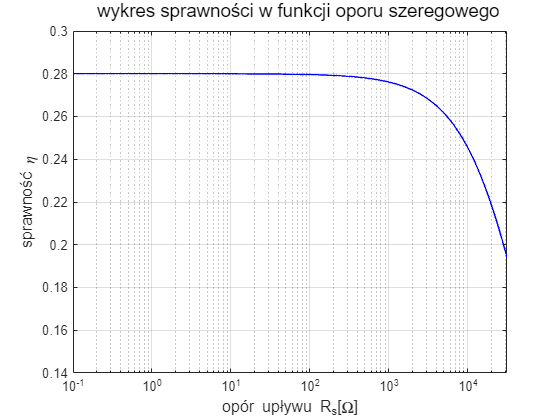

semilogx(Rs_study,etas,'color','blue','LineWidth',1.1)
xlim([1e-1,10^(4.5)]);
ylim([0.14,0.3]);
xlabel("opór upływu R_{s}[\Omega]","FontSize",12);
ylabel("sprawność \eta","FontSize",12);
text(0.2, 0.31,'wykres sprawności w funkcji oporu szeregowego ','FontSize', 14);
grid on

Źródła:

[1] Reference Air Mass 1.5 Spectra . https://www.nrel.gov/grid/solar-resource/spectra-am1.5.html